**Show a simple cosine signal; y(t) = 0.2*cos(2*pi*50*t)+cos(2*pi*20*t)**

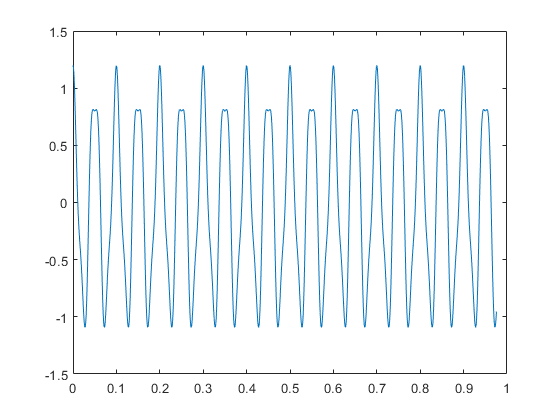

t = linspace(0,10,1024*10);
y = 0.2*cos(2*pi*50*t) + cos(2*pi*20*t);
plot(t(1:1000), y(1:1000));

**Implement fast fourier transform**

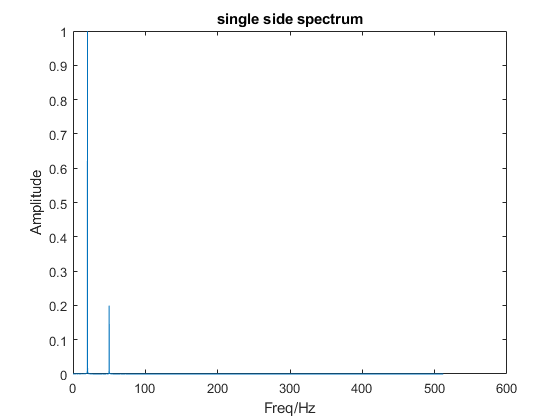

% sampling interval
Ts = 10/(10*1024);

% sampling frequency
Fs = 1/Ts;

% sampling points
N = 10*1024;

Y = fft(y);

% P1(single side spectrum)
P1 = abs(Y(1:N/2))/N*2;

f = Fs/N*(0:(N-1)/2);

plot(f, P1);
xlabel("Freq/Hz");
ylabel("Amplitude");
title("single side spectrum");